% Creates the first path required for Milestone 3
% Hard coded, I can change this if we want to make it more versatile

initialX = 0

initialX = 0

initialY = 10

initialY = 10


% Size of path area
sizeX = 50 % (m)

sizeX = 50

sizeY = 50 % (m)

sizeY = 50


% Location of obstacle
o_posX = 25 % (m)

o_posX = 25

o_posY = 10 % (m)

o_posY = 10

o_radius = 5 % (m)

o_radius = 5

o_clearance = 10 % (m)

o_clearance = 10


o_X1 = o_posX - o_radius - o_clearance 

o_X1 = 10

o_Y1 = o_posY + o_radius + o_clearance 

o_Y1 = 25

o_X2 =  o_posX + o_radius + o_clearance 

o_X2 = 40

o_Y2 = o_posY

o_Y2 = 10


% Initial parameters
dt = 0.1

dt = 0.1000

time = 0

time = 0

path_posX = initialX;
path_posY = initialY;

% Vectors
timelist = [0]

timelist = 0

positionX = [initialX];
positionY = [initialY];

while path_posX < o_X1
    path_posX = path_posX + dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];
    
    time = time + dt;
    timelist = [timelist, time];
end

while path_posY < o_Y1
    path_posY = path_posY + dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];

    time = time + dt;
    timelist = [timelist, time];
end

while path_posX < o_X2
    path_posX = path_posX + dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];
    
    time = time + dt;
    timelist = [timelist, time];
end

while path_posY > o_Y2
    path_posY = path_posY - dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];

    time = time + dt;
    timelist = [timelist, time];
end

while path_posX < sizeX
    path_posX = path_posX + dt;
    positionX = [positionX, path_posX];
    positionY = [positionY, path_posY];
    
    time = time + dt;
    timelist = [timelist, time];
end

outputArray =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4

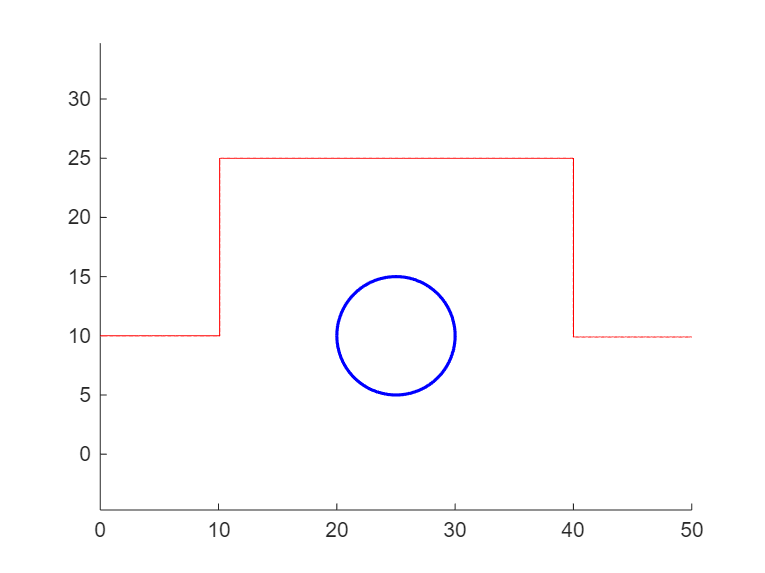


figure
hold on
axis equal
rectangle('Position',[o_posX-o_radius, o_posY-o_radius, 2*o_radius, 2*o_radius], 'Curvature',[1 1],'EdgeColor','b','LineWidth',1.5);
plot(positionX, positionY, 'r')
hold off